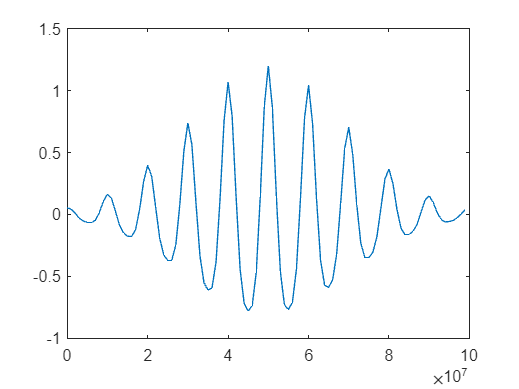

df = 1e6;
f = 0:df:0.1e9-df;
n = length(f);
t0 = 100e-9;
S = exp(2j*pi*t0*f);
S = S+0.2*exp(2j*pi*2*t0*f);
S = S.*gausswin(n)';

plot(f,real(S))

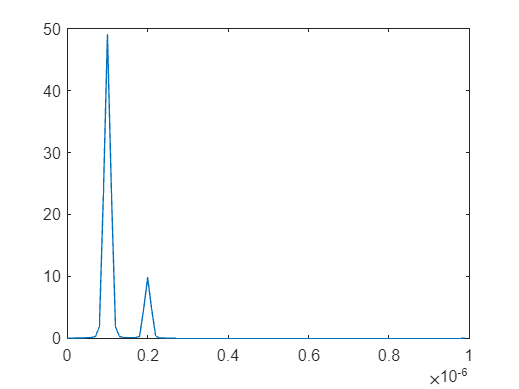


dt = 1/df/n;
t = 0:dt:(n-1)*dt;
s = fft(S);

plot(t,abs(s))


[~,m] = max(abs(s));